## Тест 1

Точное решение: u(x,t) = sinx+cost

resh = @(x,t)(sin(x)+cos(t));
h = 1e-2;
a = 1;
k = 3;
%tau = h^2/(2*k);
tau = 1e-3;
T = 0.5;
f = @(x,t)(-sin(t)+3*sin(x));
mu = @(x) (sin(x)+1);
mu_1 = @(t) (cos(t));
mu_2 = @(t) (sin(1)+cos(t));
tic;
u_1 = ROS0(h, a, tau, T, mu, mu_1, mu_2, k, f);
t_1 = toc

t_1 = 0.4099

tic;
u_2 = CROS(h, a, tau, T, mu, mu_1, mu_2, k, f);
t_2 = toc

t_2 = 0.5433

График точного решения:

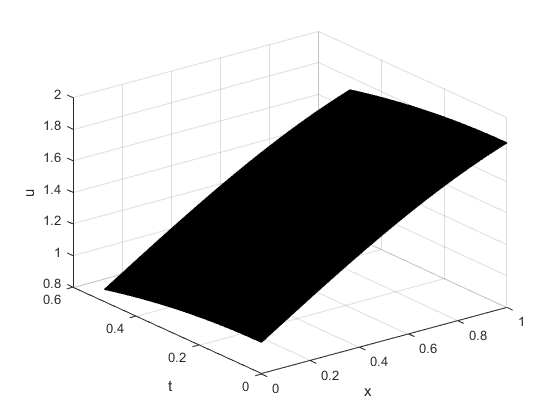

[x,t, u_toch] = tochn(a,T,tau,h,resh);
surf(x,t,u_toch);
xlabel('x');
ylabel('t');
zlabel('u');

График численного решения явным методом: 

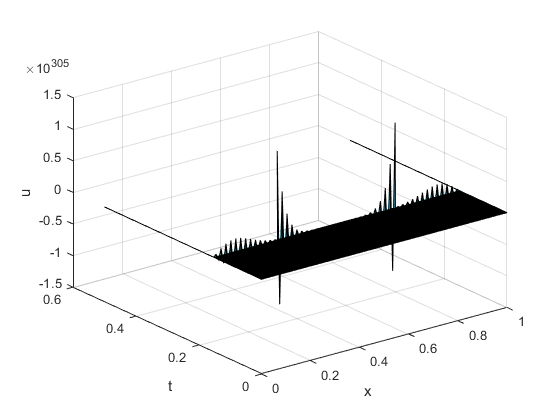

surf(x,t,u_1);
xlabel('x');
ylabel('t');
zlabel('u');

График численного решения неявным методом: 

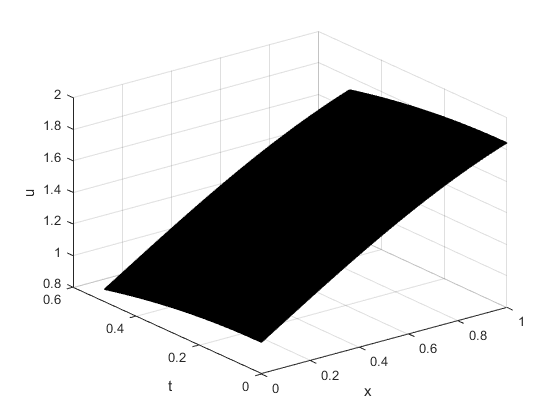

surf(x,t,u_2);
xlabel('x');
ylabel('t');
zlabel('u');

d_1 = u_1 - u_toch;
d_2 = u_2 - u_toch;

Макимальное отклонение явного метода и график откланения:

max(max(abs(d_1)))

ans = Inf

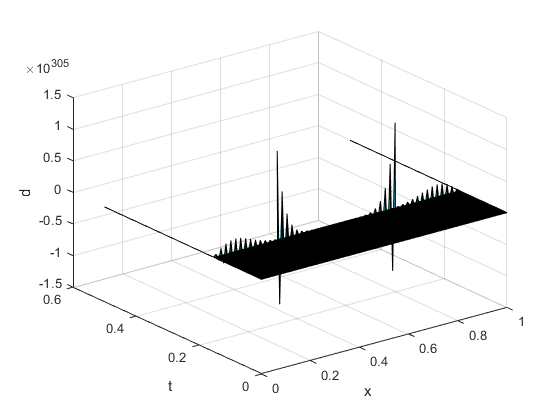

surf(x,t,d_1);
xlabel('x');
ylabel('t');
zlabel('d');

Макимальное отклонение неявного метода и график откланения:

max(max(abs(d_2)))

ans = 0.0019

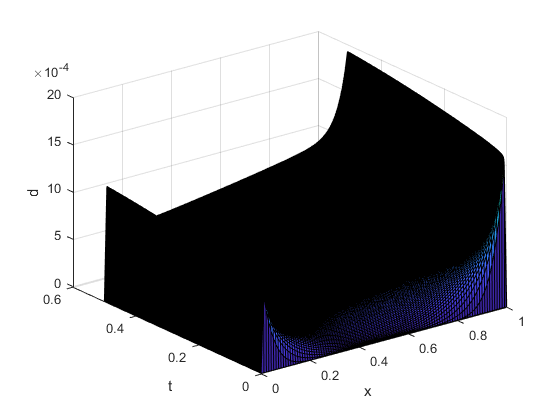

surf(x,t,d_2);
xlabel('x');
ylabel('t');
zlabel('d');

## Тест 2

Точное решение: u(x,t) = cosx*exp^(-t)

resh = @(x,t)(cos(x).*exp(-t));
h = 1e-2;
a = 1;
k = 4;
%tau = h^2/(2*k);
tau = 1e-3;
T = 0.5;
f = @(x,t)(3*cos(x).*exp(-t));
mu = @(x) (cos(x));
mu_1 = @(t) (exp(-t));
mu_2 = @(t) (cos(1)*exp(-t));
tic;
u_1 = ROS0(h, a, tau, T, mu, mu_1, mu_2, k, f);
t_1 = toc

t_1 = 0.8505

tic;
u_2 = CROS(h, a, tau, T, mu, mu_1, mu_2, k, f);
t_2 = toc

t_2 = 0.1948

График точного решения:

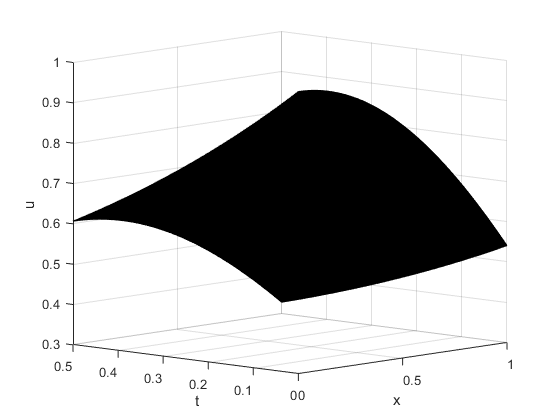

[x,t, u_toch] = tochn(a,T,tau,h,resh);
surf(x,t,u_toch);
xlabel('x');
ylabel('t');
zlabel('u');
view([-47.211 8.636]);

График численного решения явным методом: 

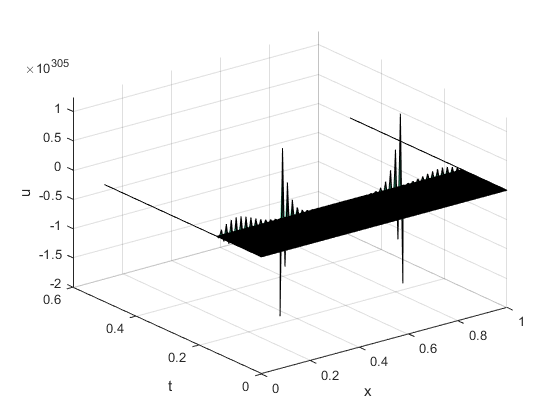

surf(x,t,u_1);
xlabel('x');
ylabel('t');
zlabel('u');

График численного решения неявным методом: 

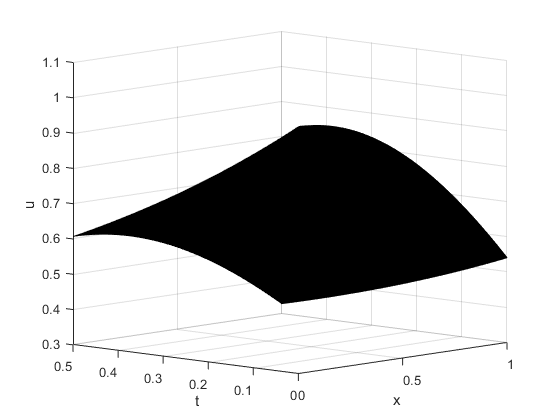

surf(x,t,u_2);
xlabel('x');
ylabel('t');
zlabel('u');
view([-47.211 8.636])

d_1 = u_1 - u_toch;
d_2 = u_2 - u_toch;

Макимальное отклонение явного метода и график откланения:

max(max(abs(d_1)))

ans = Inf

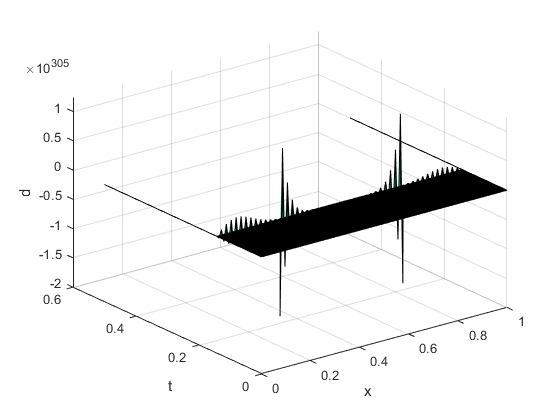

surf(x,t,d_1);
xlabel('x');
ylabel('t');
zlabel('d');

Макимальное отклонение неявного метода и график откланения:

max(max(abs(d_2)))

ans = 0.0018

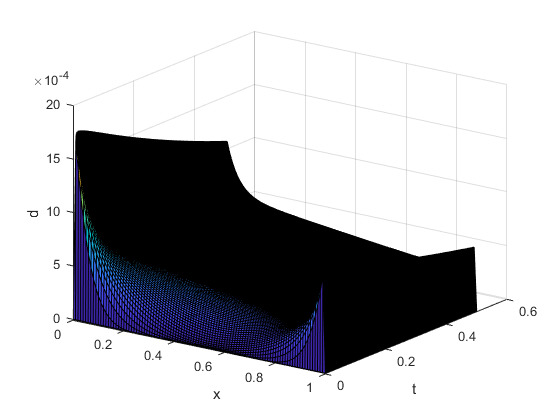

surf(x,t,d_2);
xlabel('x');
ylabel('t');
zlabel('d');
view([35.81792 23.20231]);

## Тест 3

Точное решение: u(x,t) =(sint-x)*exp(x)

resh = @(x,t)((sin(t)-x).*exp(x));
h = 1e-2;
a = 1;
k = 5;
%tau = h^2/(2*k);
tau = 1e-3;
T = 0.5;
f = @(x,t)((cos(t)+5*x+10-5*sin(t)).*exp(x));
mu = @(x) (-x.*exp(x));
mu_1 = @(t) (sin(t));
mu_2 = @(t) ((sin(t)-1)*exp(1));
tic;
u_1 = ROS0(h, a, tau, T, mu, mu_1, mu_2, k, f);
t_1 = toc

t_1 = 0.0475

tic;
u_2 = CROS(h, a, tau, T, mu, mu_1, mu_2, k, f);
t_2 = toc

t_2 = 0.1950

График точного решения:

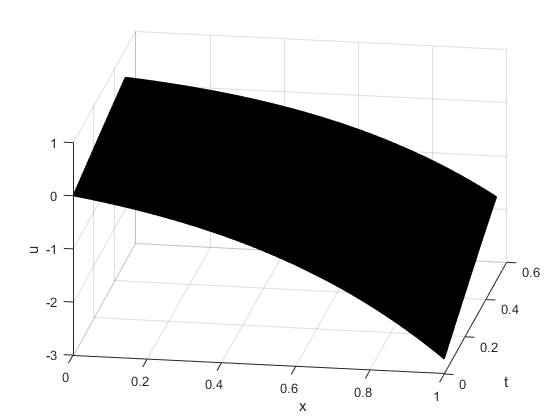

[x,t, u_toch] = tochn(a,T,tau,h,resh);
surf(x,t,u_toch);
xlabel('x');
ylabel('t');
zlabel('u');
view([9.60 28.06])

График численного решения явным методом: 

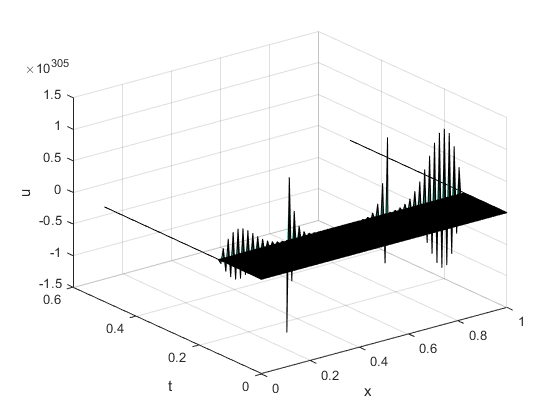

surf(x,t,u_1);
xlabel('x');
ylabel('t');
zlabel('u');

График численного решения неявным методом: 

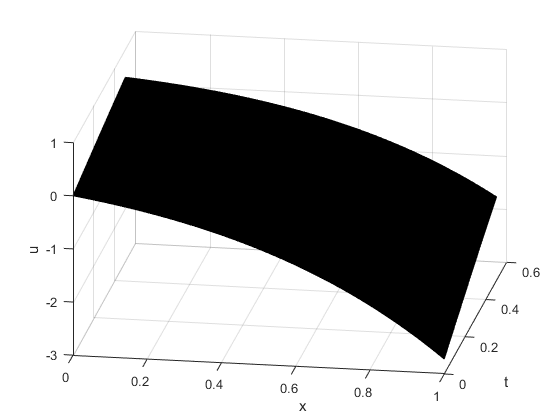

surf(x,t,u_2);
xlabel('x');
ylabel('t');
zlabel('u');
view([9.60 28.06])

d_1 = u_1 - u_toch;
d_2 = u_2 - u_toch;

Макимальное отклонение явного метода и график откланения:

max(max(abs(d_1)))

ans = Inf

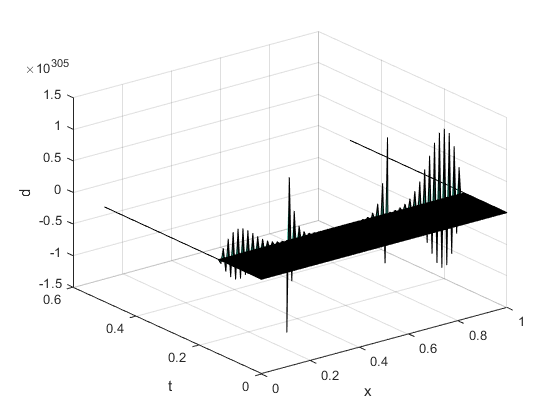

surf(x,t,d_1);
xlabel('x');
ylabel('t');
zlabel('d');

Макимальное отклонение неявного метода и график откланения:

max(max(abs(d_2)))

ans = 0.0049

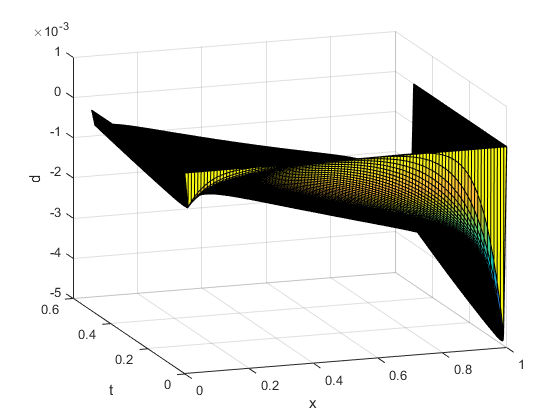

surf(x,t,d_2);
xlabel('x');
ylabel('t');
zlabel('d');
view([-19.1781 18.3468]);

## Тест 4

Точное решение: u(x,t) =exp(t+x)

resh = @(x,t)(exp(x+t));
h = 1e-2;
a = 1;
k = 2;
%tau = h^2/(2*k);
tau = 1e-3;
T = 0.5;
f = @(x,t)(-exp(x+t));
mu = @(x) (exp(x));
mu_1 = @(t) (exp(t));
mu_2 = @(t) (exp(t+1));
tic;
u_1 = ROS0(h, a, tau, T, mu, mu_1, mu_2, k, f);
t_1 = toc

t_1 = 0.0227

tic;
u_2 = CROS(h, a, tau, T, mu, mu_1, mu_2, k, f);
t_2 = toc

t_2 = 0.2052

График точного решения:

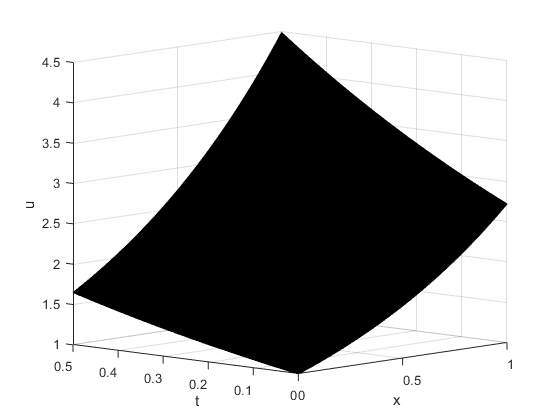

[x,t, u_toch] = tochn(a,T,tau,h,resh);
surf(x,t,u_toch);
xlabel('x');
ylabel('t');
zlabel('u');
view([-47.211 8.636]);

График численного решения явным методом: 

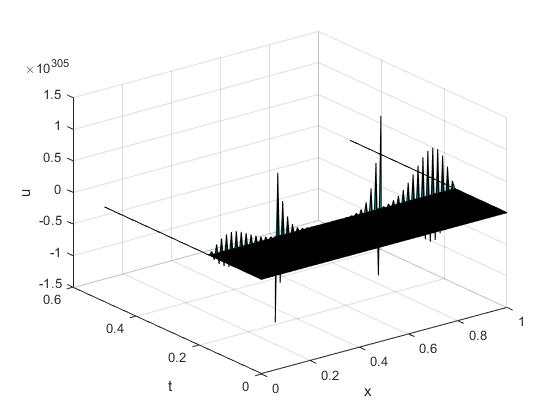

surf(x,t,u_1);
xlabel('x');
ylabel('t');
zlabel('u');

График численного решения неявным методом: 

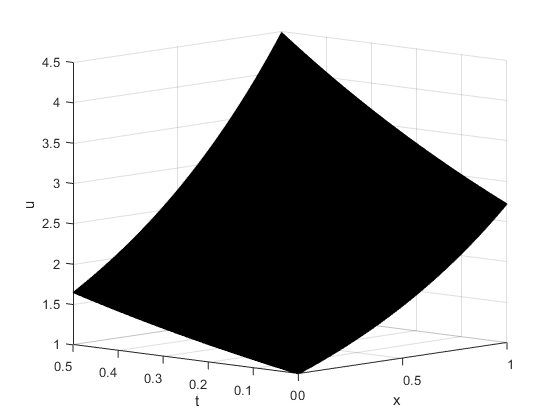

surf(x,t,u_2);
xlabel('x');
ylabel('t');
zlabel('u');
view([-47.211 8.636])

d_1 = u_1 - u_toch;
d_2 = u_2 - u_toch;

Макимальное отклонение явного метода и график откланения:

max(max(abs(d_1)))

ans = Inf

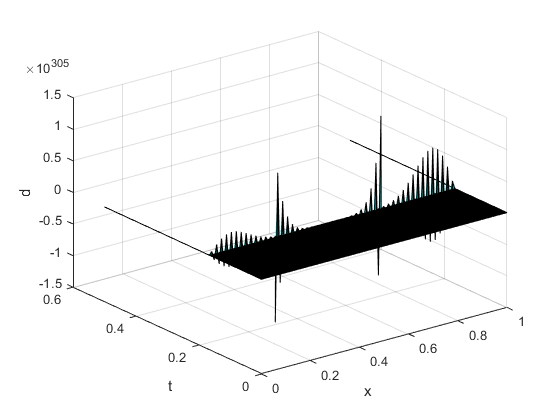

surf(x,t,d_1);
xlabel('x');
ylabel('t');
zlabel('d');

Макимальное отклонение неявного метода и график откланения:

max(max(abs(d_2)))

ans = 7.8168e-05

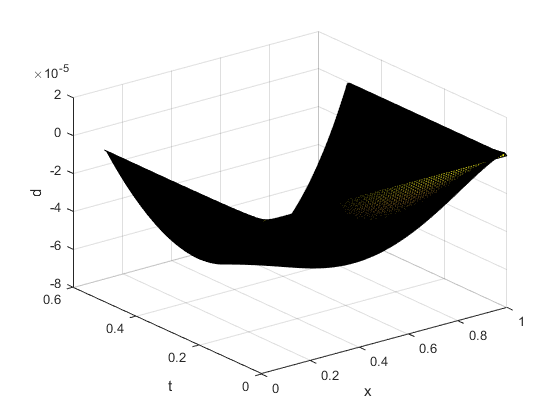

surf(x,t,d_2);
xlabel('x');
ylabel('t');
zlabel('d');

## Тест 5

Точное решение: u(x,t) = (t+1)/(x+1)

resh = @(x,t)((1+t)./(1+x));
h = 1e-2;
a = 1;
k = 6;
%tau = h^2/(2*k);
tau = 1e-3;
T = 0.5;
f = @(x,t)((1+x).^(-1)-12*(1+t).*((1+x).^(-3)));
mu = @(x)((1+x).^(-1));
mu_1 = @(t) (1+t);
mu_2 = @(t)(1+t)/2;
tic;
u_1 = ROS0(h, a, tau, T, mu, mu_1, mu_2, k, f);
t_1 = toc

t_1 = 0.8716

tic;
u_2 = CROS(h, a, tau, T, mu, mu_1, mu_2, k, f);
t_2 = toc

t_2 = 0.3181

График точного решения:

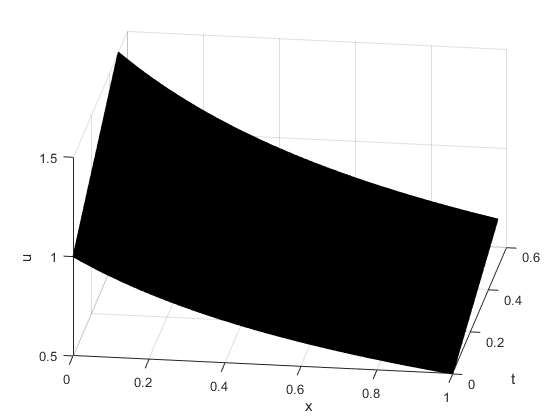

[x,t, u_toch] = tochn(a,T,tau,h,resh);
surf(x,t,u_toch);
xlabel('x');
ylabel('t');
zlabel('u');
view([8.142 32.705])

График численного решения явным методом: 

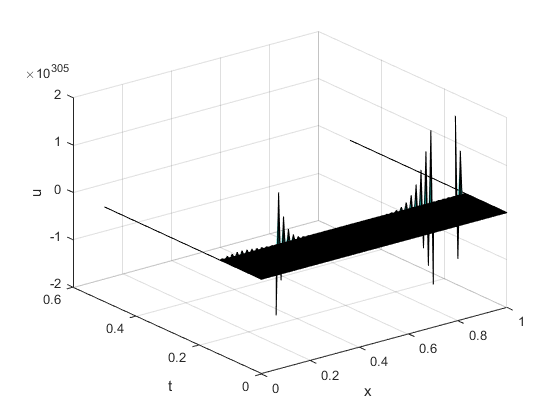

surf(x,t,u_1);
xlabel('x');
ylabel('t');
zlabel('u');

График численного решения неявным методом: 

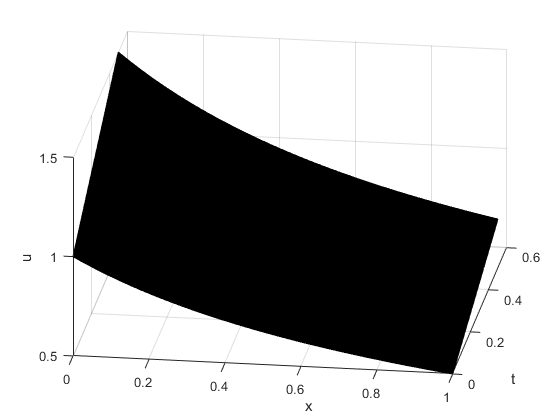

surf(x,t,u_2);
xlabel('x');
ylabel('t');
zlabel('u');
view([8.142 32.705])

d_1 = u_1 - u_toch;
d_2 = u_2 - u_toch;

Макимальное отклонение явного метода и график откланения:

max(max(abs(d_1)))

ans = Inf

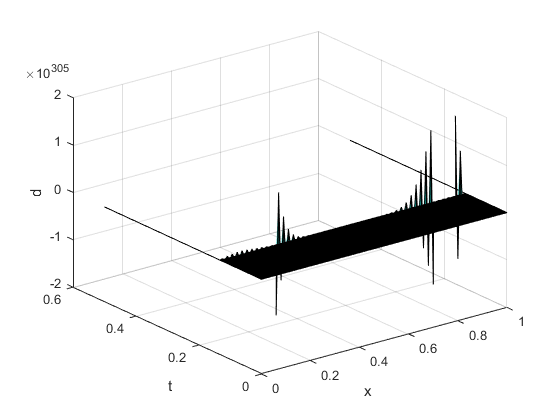

surf(x,t,d_1);
xlabel('x');
ylabel('t');
zlabel('d');

Макимальное отклонение неявного метода и график откланения:

max(max(abs(d_2)))

ans = 4.5587e-04

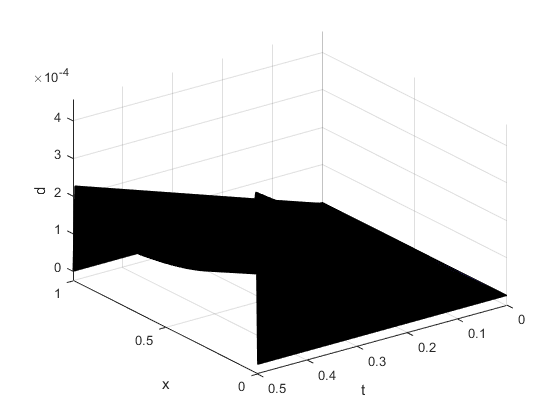

surf(x,t,d_2);
xlabel('x');
ylabel('t');
zlabel('d');
view([-126.50752 32.61114])